The purpose of this script is to create a model for harmonic motion and observe the effects of changing the parameters. A hand-waving style introduction is needed before this however. We will stay away from the math equations as this is here for intuition and not solving of differential equations. During the script we will change the spring constant, coefficient of friction and the driving force in order to observer different types of harmonic motion. First off,let's take a look briefly at our simulink model:

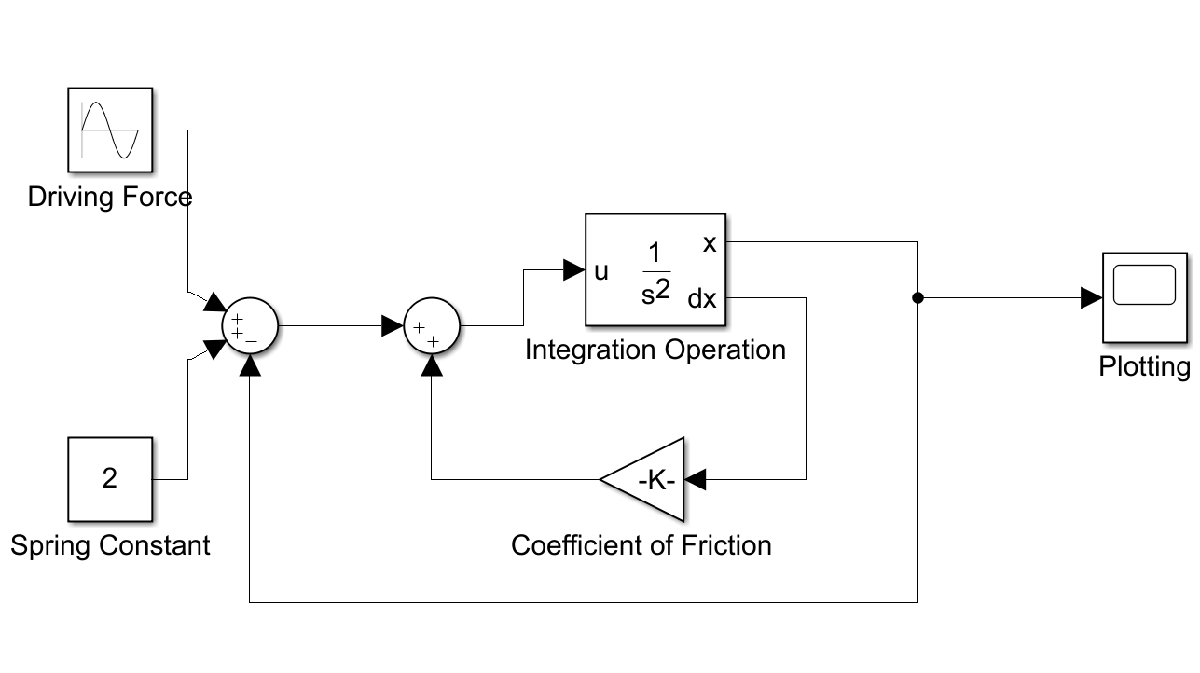

Starting from simple and working our way up:

- On the far right, we have the plotting tool, this will plot the results of the simulation for us

- On the far left, the spring constant. The units don't matter here.

- In the middle, we have our friction coefficient, in this case think of it as how much friction is created by dragging a block

- Feedback loops in the left-middle. These control if the signal is added or subtracted to the input signal

- Top left, the driving force. this is a function that will apply force to our system.

- Top middle, our integrator. This will be numerically integrating the signal that is recieved as input. The input signal here is the force action of the object in the system.

First, we are going to observe simple harmonic motion

%the following parameters are setting up this system to illustrate simple
%harmonic motion. This is the type of motion that will be observed by
%ignoring friction and absent of driving force.
model='HM_model.slx';
obj=load_system(model);
set_param('HM_model/Driving Force','Amplitude','0')
set_param('HM_model/Spring Constant','Value','3')
set_param('HM_model/Coefficient of Friction','Gain','0')
set_param(bdroot,'SimulationCommand','Update')
open_system(model) %this will open a simulink window
output=sim(model);

Unrecognized function or variable 't'.

Now popping over to the model we can see 